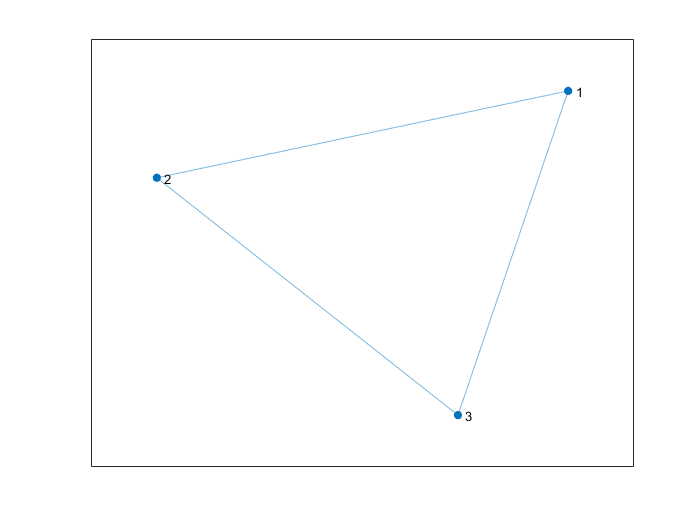

A = [0 1 1;
     1 0 1;
     1 1 0];
plot(graph(A))

## Fiedler Vector and Resistance Curver

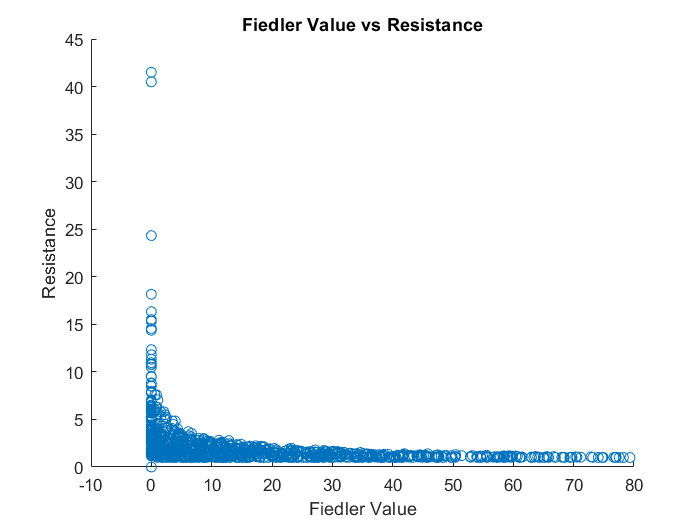

trials = 1000;
n = 5;
F = zeros(trials, 1);
R = zeros(trials, 1);
for t=1:trials
    % Make graph
    A = generate_random_network('ER', randi([2, 100]), rand);
    % Compute Laplacian = D - A
    L = diag(sum(A)) - A;
    eigenvalues = eig(L);
    % Compute fiedler value
    fiedler = eigenvalues(2);
    % Compute Resistance
    idxs = find(abs(eigenvalues) > 0.0001);
    first_nonzero = min(idxs);
    eigenvalues = eigenvalues(first_nonzero:end);
    resistance = length(A) * sum(1/eigenvalues);
    % Save
    F(t) = fiedler;
    R(t) = resistance;
end

% Make plot
scatter(F, R);
title('Fiedler Value vs Resistance');
xlabel('Fiedler Value'); ylabel('Resistance');

## Fiedler Vector for all (Connected) 4 Node Graphs

A1 =[0 1 0 1;
     1 0 0 0;
     0 0 0 1;
     1 0 1 0;];
D1 = diag(sum(A1));
L1 = D1 - A1;

A2 =[0 1 0 1;
     1 0 1 0;
     0 1 0 1;
     1 0 1 0;];
D2 = diag(sum(A2));
L2 = D2 - A2;

A3 =[0 1 1 1;
     1 0 0 0;
     1 0 0 1;
     1 0 1 0;];
D3 = diag(sum(A3));
L3 = D3 - A3;

A4 =[0 1 1 1;
     1 0 1 0;
     1 1 0 1;
     1 0 1 0;];
D4 = diag(sum(A4));
L4 = D4 - A4;

A5 =[0 1 1 1;
     1 0 1 1;
     1 1 0 1;
     1 1 1 0;];
D5 = diag(sum(A5));
L5 = D5 - A5;

% Compute Fiedler Vectors
fiedler_vectors = []


fiedler_vectors =

     []



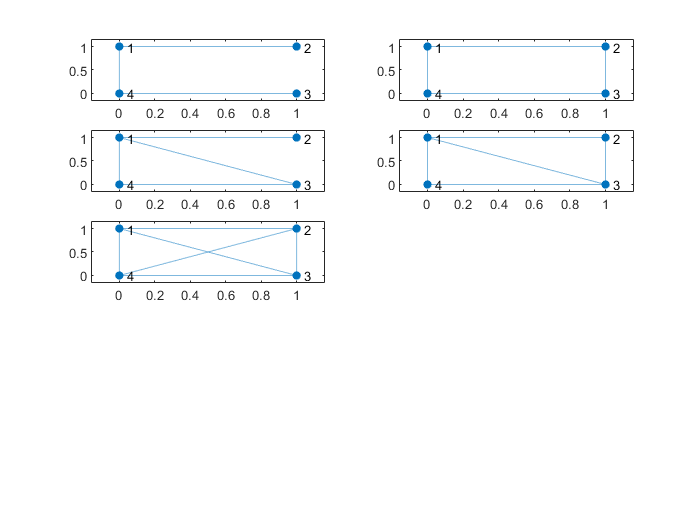

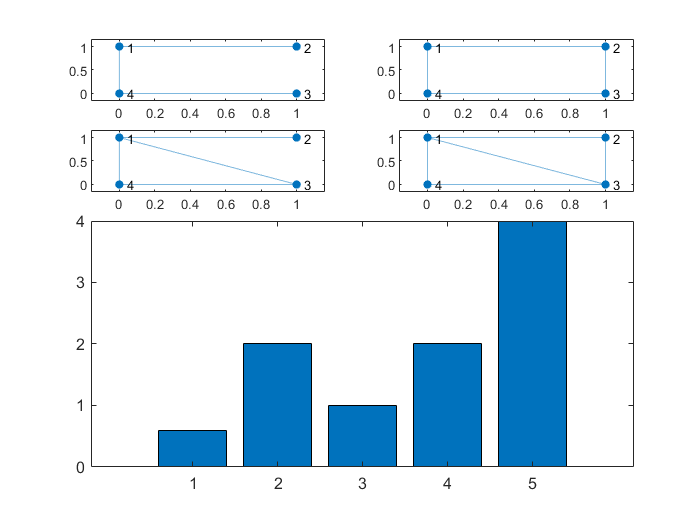

e = eigs(L1); fiedler_vectors = [fiedler_vectors; e(3)];
e = eigs(L2); fiedler_vectors = [fiedler_vectors; e(3)];
e = eigs(L3); fiedler_vectors = [fiedler_vectors; e(3)];
e = eigs(L4); fiedler_vectors = [fiedler_vectors; e(3)];
e = eigs(L5); fiedler_vectors = [fiedler_vectors; e(3)];

xcord = [0 1 1 0];
ycord = [1 1 0 0];
figure;
subplot(5,2,1); title('G1');
plot(graph(A1), 'XData', xcord, 'YData', ycord)
subplot(5,2,3); title('G2');
plot(graph(A2), 'XData', xcord, 'YData', ycord)
subplot(5,2,5); title('G3');
plot(graph(A3), 'XData', xcord, 'YData', ycord)
subplot(5,2,7); title('G4');
plot(graph(A4), 'XData', xcord, 'YData', ycord)
subplot(5,2,9); title('G5');
plot(graph(A5), 'XData', xcord, 'YData', ycord)
subplot(5,2,[2 4 6 8 10]); bar(fiedler_vectors);



nchoosek()
